# Расчёт полосно-заграждающего фильтра

### Импорт аудио

Загрузим входной аудио-файл, который мы будем пропускать через фильтр, и послушаем его:

[x,fs] = audioread('energy.mp3');
soundsc(x,fs);

### Зададим объект спецификации фильтра

Мы хотим рассчитать полосно-заграждающий фильтр со следующей спецификацией:

Полоса пропускания - от 0 до 500 Гц

Полоса заграждения - от 1000 до 4000 Гц

Полоса пропускания - от 4500 Гц до 22050 Гц

Пульсации в полосах пропускания - не более 1 дБ

Подавление в полосе заграждения - не менее 10 дБ

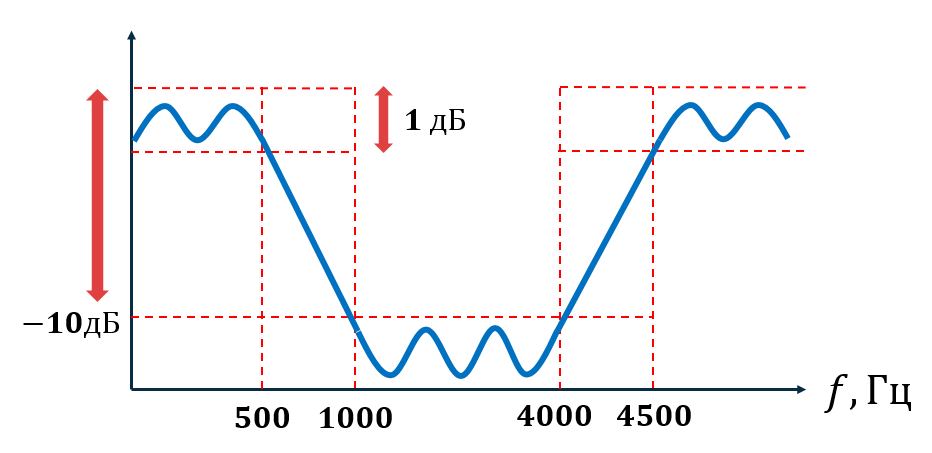

Объект спецификации формируется при помощи команды **fdesign**. В нашем случае мы сразу указываем тип специфкации **banstop**, и задаём набор численных значений параметров:

d = fdesign.bandstop('Fp1,Fst1,Fst2,Fp2,Ap1,Ast,Ap2',500,1000,4000,4500,1,10,1,fs)

### Посчёт коэффициентов фильтра

Для вычисления коэффицентов фильтра мы используем функцию **design**, которой мы передаём объект спецификации фильтра и тип фильтра. В нашем случае это КИХ-фильтр типа **equiripple**. Оценим характеристики фильтра и их соответствие спецификации в программе **FVTOOL**: 

Hd = design(d,'equiripple')
fvt1 = fvtool(Hd);
axis([0,5,-30,10]);

Отобразим коэффциенты числтеля передаточной функции фильтра на графике:

stem(Hd.Numerator,'LineWidth',2);
grid on;
xlim([0 63]);

### Применение фильтра

Отфильтруем входной сигнал командой **filter** и прослушаем результат:

y = filter(Hd,x);
soundsc(y,fs);

### Сравнение спектов входного и выходного сигналов

Вставьте сюда команды для отображения спектра сигналов **x** и **y**: